# DSZOB, cvičenie 7.

## **Zadanie:**

## **Úloha 1: **Formantová analýza reči

Vyberte si a rôzne samohlásky ( á,é,í,ó,ú ) a nasnímajte záznam dlhej výslovnosti každej z nich. Pre ďalšie spracovanie stačí postupnosť asi 3000-4000 vzorkov. Vizualizujte fourierské amplitudové spektrum pre každú z nasnímaných samohlásiek. Môžete použiť funkciu: specgram() alebo spectrogram(). 

Skúste zo spektra odhadnúť 1. a 2. formant! 

Posúďte ako odpovedajú Vaše odhadnuté hodnoty tabuľke: Hodnoty priemerných formantov F1 a F2

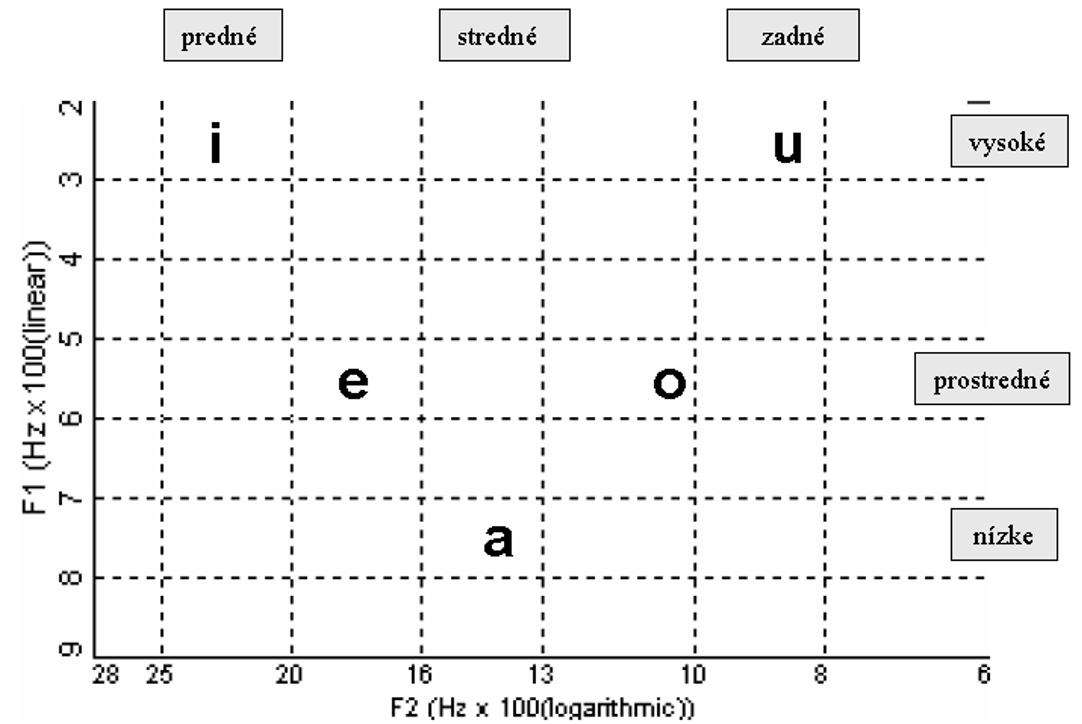

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

fs = 44100;

%recorder = audiorecorder(fs,16,1);
%recordblocking(recorder, 3);
%y_a = getaudiodata(recorder)';
%audiowrite('a.wav',y_a,fs);

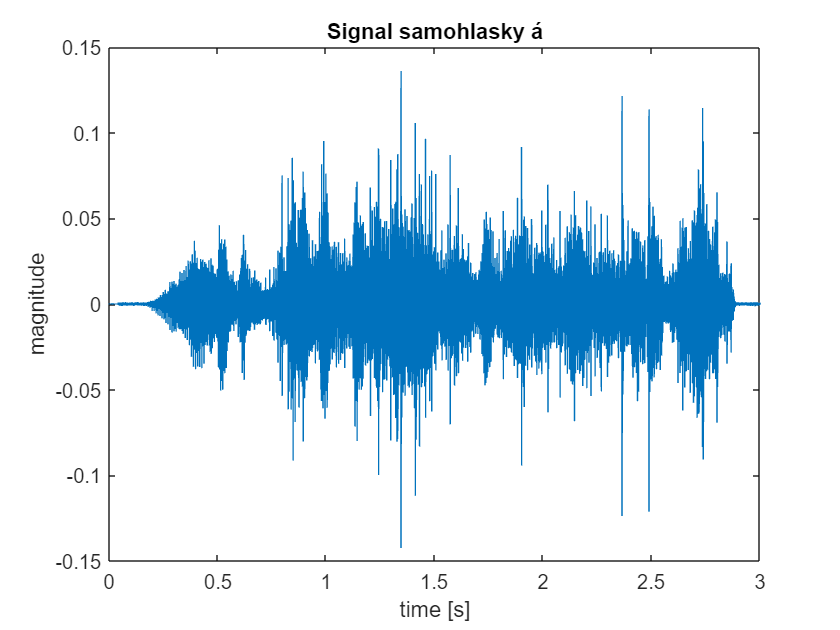

[y_a,fs] = audioread('a.wav');
x = 0:1/fs:3;
x = x(1:132300);
plot(x,y_a)
title("Signal samohlasky á")
xlabel("time [s]")
ylabel("magnitude")

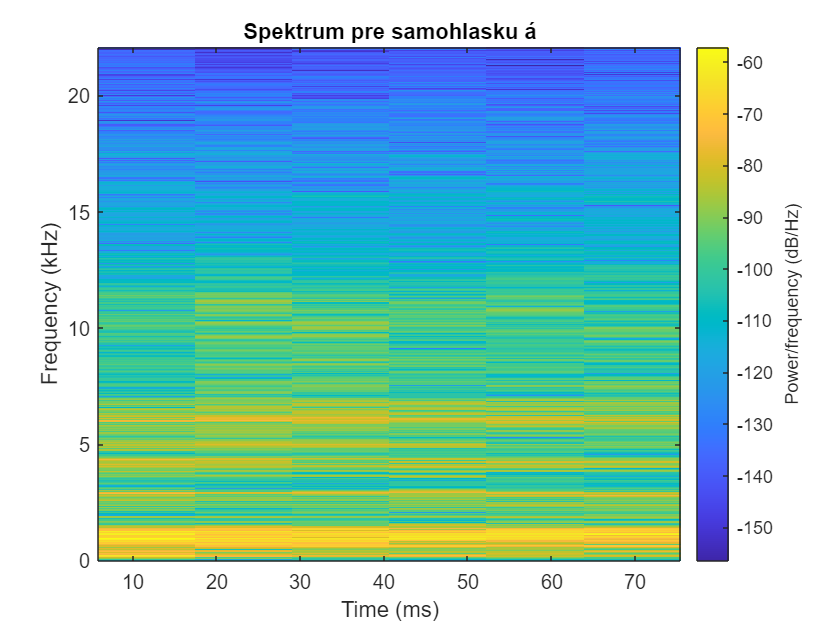

spectrogram(y_a(44101: 48100),hamming(1024), 512, 1024, 44100, 'yaxis')
title('Spektrum pre samohlasku á')

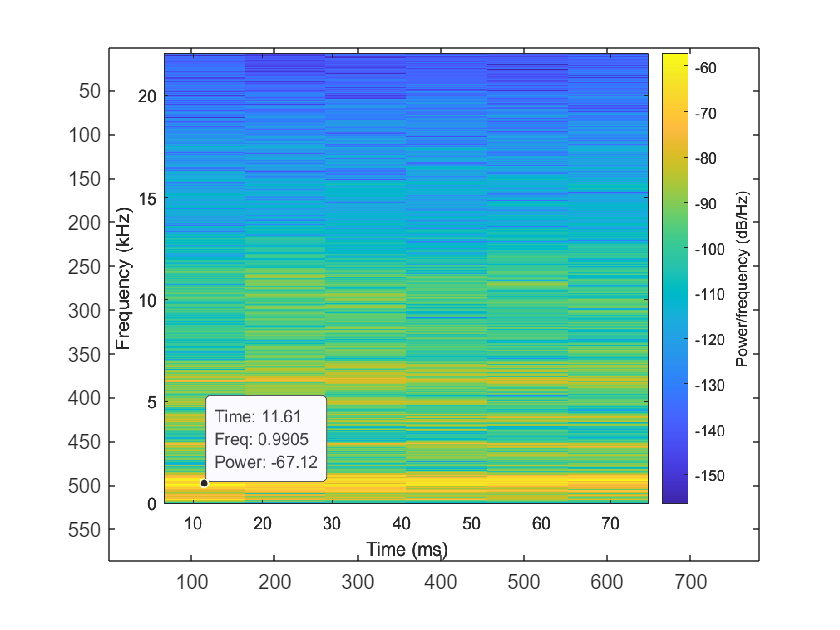

image(imread('a.png'));

Podľa prednášky, formant pre samohlásku á je 800-1200 Hz. V mojom prípade mala samohláska á dominantnú frekvenciu približne 1000 Hz, čo presne spadá do tohto intervalu.

%recorder = audiorecorder(fs,16,1);
%recordblocking(recorder, 3);
%y_e = getaudiodata(recorder)';
%audiowrite('e.wav',y_e,fs);

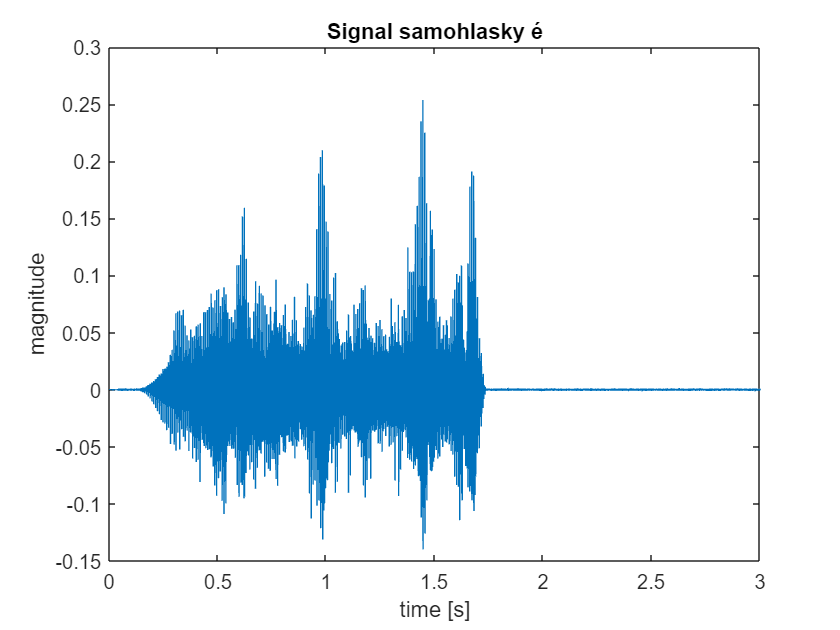

[y_e,fs] = audioread('e.wav');
x = 0:1/fs:3;
x = x(1:132300);
plot(x,y_e)
title("Signal samohlasky é")
xlabel("time [s]")
ylabel("magnitude")

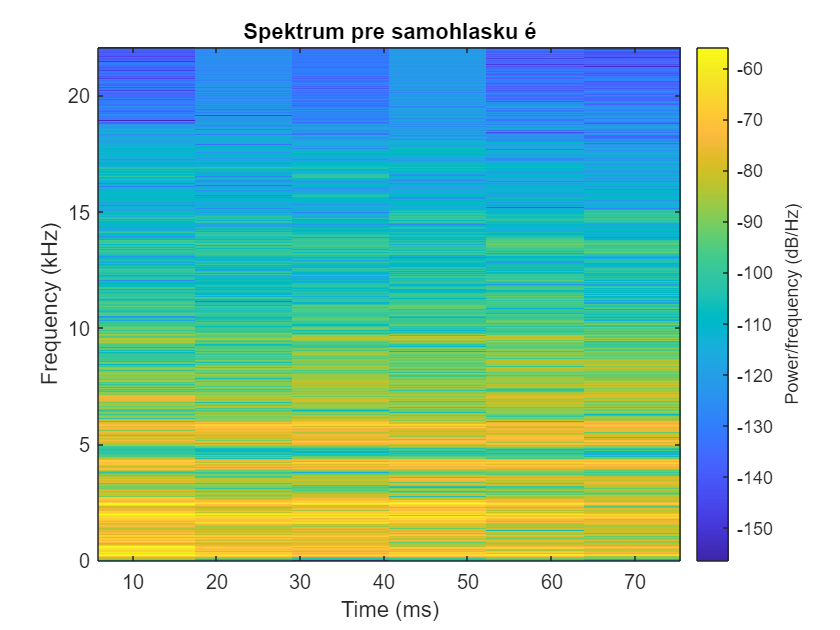

spectrogram(y_e(44101: 48100),hamming(1024), 512, 1024, 44100, 'yaxis')
title('Spektrum pre samohlasku é')

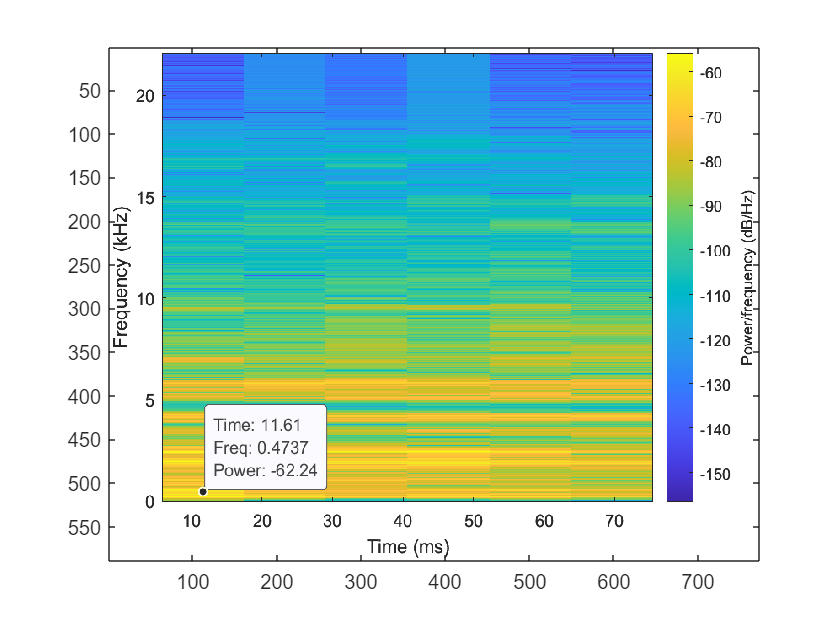

figure();
image(imread('e_1.png'));

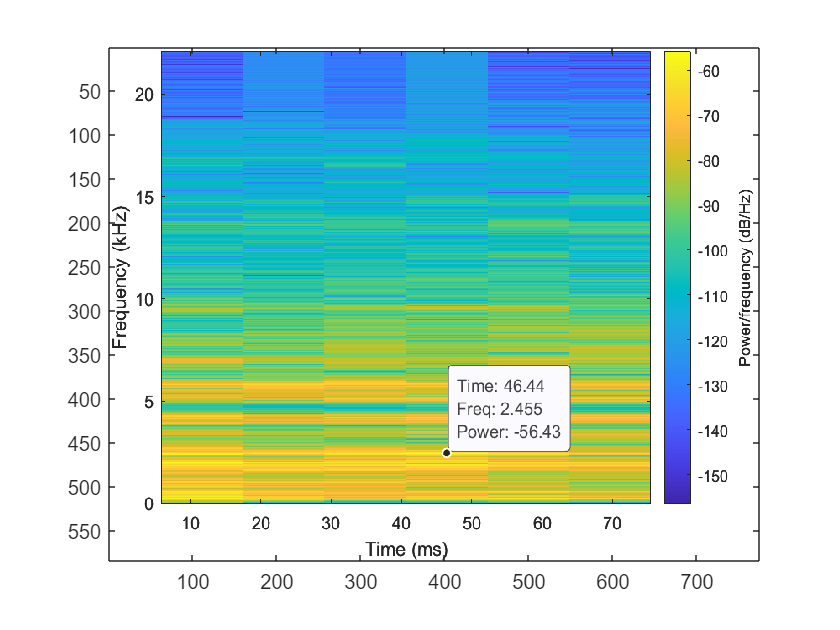

figure();
image(imread('e_2.png'));

Podľa prednášky, formanty pre samohlásku é sú 400 - 600 Hz a 2200 - 2600 Hz. Na spektrograme vidieť, že aj v mojom prípade frekvencie spadajú do týchto intervalov.

## **Úloha 2: Cepstrum**

Vytvorte echo do zvoleného signálu, napr. do nasnímaného zvuku ladičky.

Vypočítajte komplexné cepstrum tohto signálu na zvolenom intervale (pomôcka: `cceps()``)`

Vizualizujte toto cepstrum a zistite, či sa v signále cepstra  na x-vej pozícii odpovedajúcej časovému offsetu echa nachádza lokálne maximum.

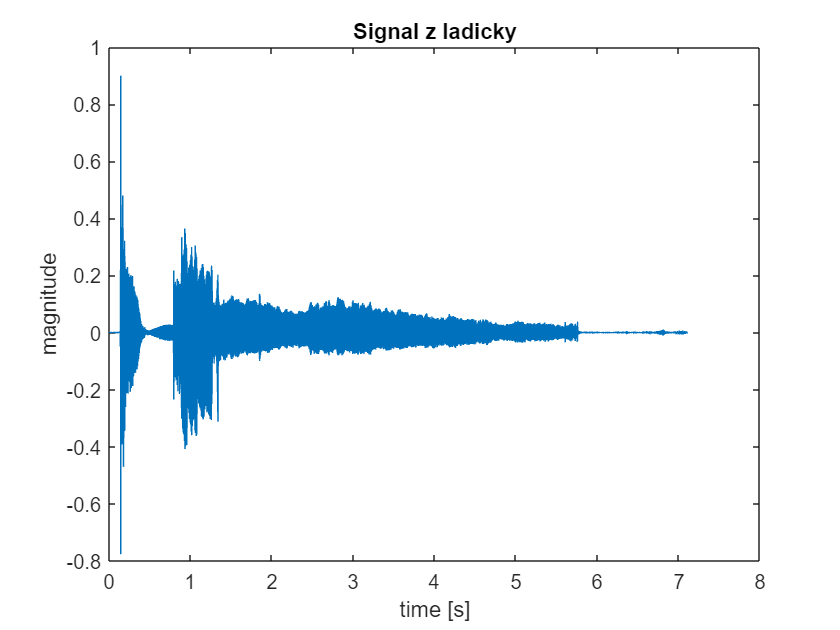

[y_fork,fs_fork] = audioread('a.m4a');
x_fork = 0:1/fs_fork:length(y_fork)/fs_fork;
x_fork = x_fork(1:313344);
figure();
plot(x_fork,y_fork)
title("Signal z ladicky")
xlabel("time [s]")
ylabel("magnitude")

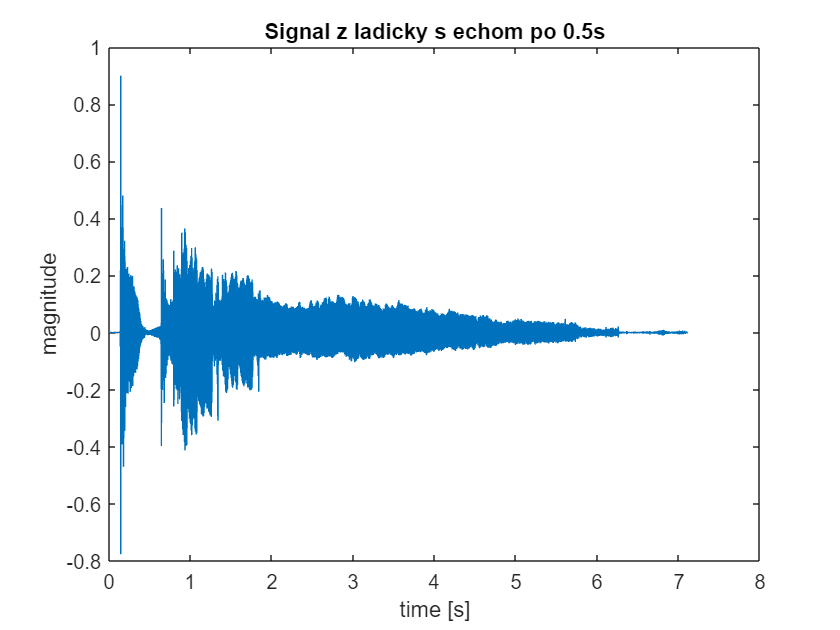

new_y = y_fork' + 0.5*[zeros(1,22050) y_fork(1:len)'];
plot(x_fork', new_y)
title("Signal z ladicky s echom po 0.5s")
xlabel("time [s]")
ylabel("magnitude")

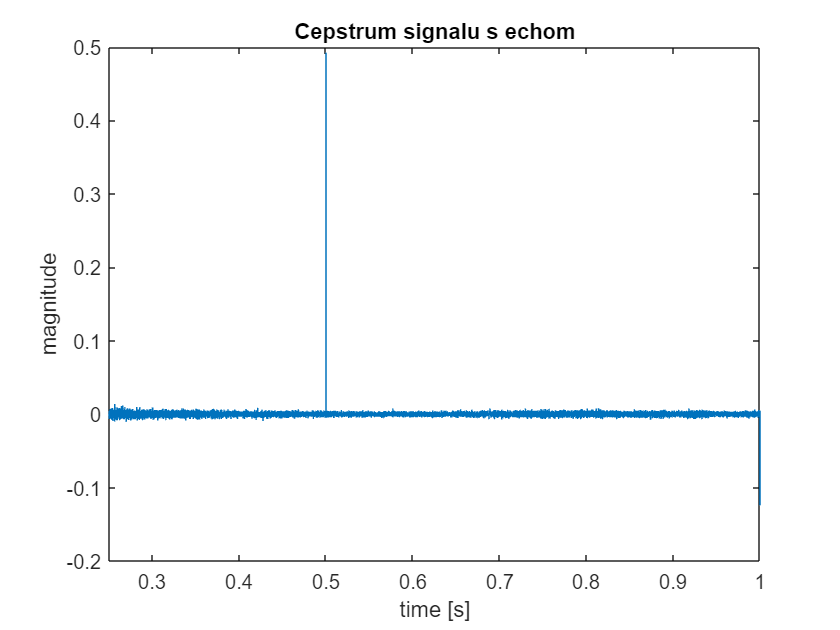

cepstrum = cceps(new_y);
plot(x_fork', cepstrum)
xlim([0.25,1])
title("Cepstrum signalu s echom")
xlabel("time [s]")
ylabel("magnitude")

Na vizualizácii (po priblížení) cepstra signálu s echom vidíme jeden peak/lokálne maximum práve v 0.5s, čo bol práve offset echa, ktoré bolo do signálu pridané.